# 

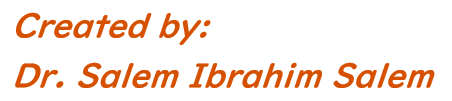

**Student Name(In English)**: Andreiev Maksym

**Student ID**: 2022m666

# **Assignment No. (9)**

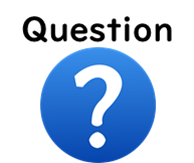

***Q1. *** Create a (2-rows & 1-column) subplot and plot the function [$y=x^2 e^{-x}$] and its derivative [$y_d =2xe^{-x} -x^2 e^{-x}$] for $x$ ($0\le x\le 3$) into these subplots, considering the following format:

               >> In the top subplot        >> plot $\left(x\right)$ vs $\left(y\right)$ using **blue** **solid** line with **asterisk** markers 

               >> In the bottom subplot  >> plot $\left(x\right)$ vs $\left(y_d \right)$ using **red** **solid** line with **circle** markes

               >> y-axis limit = -0.6 ~ 0.6    **> For the two subplot**

               >> Display major grid            **> For the two subplot**

               >> Insert legend "**Y-Func.**" &  "**Y-Derivative**"  >>> **For top and bottom subplots, respectively. **

               >> legend locatiot is south west  **> For the two subplots.**

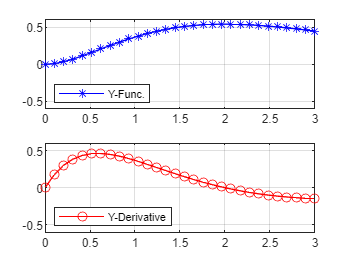

close all
x = linspace(0, 3, 30);
y = x.^2.*exp(-x);
yd = 2*x.*exp(-x) - x.^2.*exp(-x);
subplot(2, 1, 1)
plot(x, y, 'b-*')
ylim([-0.6, 0.6]);
legend("Y-Func.", "location", 'southwest')
grid on
subplot(2, 1, 2)
plot(x, yd, 'r-o')
ylim([-0.6, 0.6]);
legend("Y-Derivative", "location", 'southwest')
grid on

***Q2. *** Create (1-row & 2 columns) subplots and Plot the function [$y=x^2 e^{-x}$]  for x  $\left(0\le x\le 10\right)$ **in the two subplot**, considering the following format:

               >> In the left subplot  >> plot $\left(x\right)$ vs $\left(y\right)$ using **normal plot **command with line width = 1.3.

               >> In the right subplot >> plot $\left(x\right)$ vs $\left(y\right)$ using  **Vertical Bar Plot**.

               >> `Y`-axis label = "Amplitude"   **> For the left subplot only**

               >> Insert legend "**Y-Plot**" & "**Y-Bar**"  >>> **For left and right subplots, respectively. **

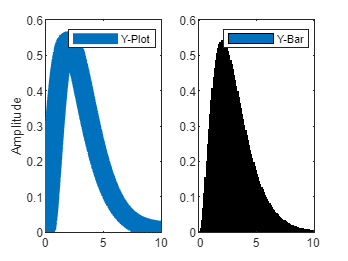

close all

x = linspace(0, 10, 100);
y = x.^2.*exp(-x);

subplot(1, 2, 1)
plot(x, y, "LineWidth", 13)
ylabel("Amplitude")
legend("Y-Plot")
subplot(1, 2, 2)
bar(x, y)
legend("Y-Bar")

***Q3.*** The following table shows the monthly average high and low temperature of Kyoto city. The temperature is shown in "fahrenheit". 

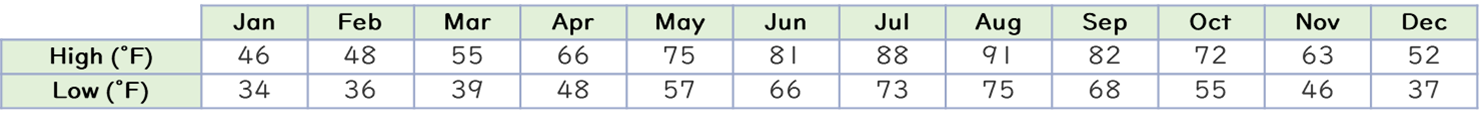

- Use the subplot command to create a 2-rows & 1-columns subplot figure.

               >> In the top subplot        >> plot months vs high temperature use **Vertical Bar Plot**

               >> In the bottom subplot  >> plot months vs low temperature use **Vertical Bar Plot** 

               >> Title is"**Monthly Average Temperature - Kyoto**"  >>> **For the top subplot only**

               >> x-axis label is "**Months**"  >>> **For the bottom subplot only**

               >> y-axis label is "**High** **Temp (F)**"  >>> **For the top subplot only**

               >> y-axis label is "**Low** **Temp (F)**"  >>> **For the bottom subplot only**

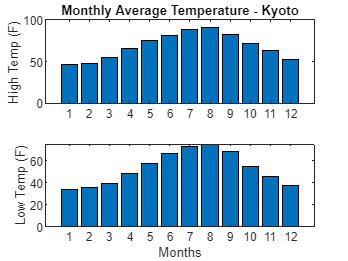

close all
% define months
months = 1:12;  % linspace(1, 12,12);

% define the temperature in fahrenheit 
high_f = [46 48 55 66 75 81 88 91 82 72 63 52];
low_f  = [34 36 39 48 57 66 73 75 68 55 46 37];

% Plot 

subplot(2, 1, 1)
bar(months, high_f)
title("Monthly Average Temperature - Kyoto")
ylabel("High Temp (F)")
subplot(2, 1, 2)
bar(months, low_f)
xlabel("Months")
ylabel("Low Temp (F)")